# A tutorial on how to use the Brain Observatory Toolbox

This tutorial will show you how to access the Brain Observatory data using MATLAB. In particular, this tutorial will show you how to:

1) Download meta information from brain observatory api and save this information as MATLAB tables

2) Build a brain_observatory_cache object to:

    a) Get general information on the brain observatory data

    b) Select sessions by specified criteria such as brain area, imaging depth and stimulus type

    c) Download NWB files of selected sessions

3) Extract imaging data from NWB files to:

    a) Get fluorescence traces

    b) Plot fluorescence traces

    c) Transform fluorescence trace into data that is in "raster format" for further analysis

## Organization of the Brain Observatory Data

Before we begin downloading data, we first want to describe the organization of the Brain Observatory Data. 

An *experiment container* contains three *sessions* (also called *experiments* or *ophys_experiments*) where recordings were made on a singe mouse, in a single brain region and at a particular imaging depth. Each of these three sessions consists of a series of "subexperiments" where a particular stimulus set was shown. NWB files downloaded from the Allen Institute API each consist of data from a single session. As described below, all data that we extract into "raster format" consists of data from a single "subexperiment" where a particular stimulus set was shown. 

Note: within an experiment container the same stimuli might be repeated in different sessions (i.e., different sessions can have the same "subexperiment type").  For example, Natural Movie 1 is shown in all three sessions in an experiment container. For more information see: [http://alleninstitute.github.io/AllenSDK/brain_observatory.html](http://alleninstitute.github.io/AllenSDK/brain_observatory.html)

## 1) Setting the path and downloading the meta data 

To start our analysis we need to set the path to the Brain Observatory Toolbox:

% set this to the path to the Brain-Observatory Toolbox
bot_dir_name = 'Brain-Observatory-Toolbox/';

% add path to MATLAB's search path
addpath(bot_dir_name)

Next we will download the meta information which is stored in manifest files on the Allen API.  We can do this using the function get_manifest_info_from_api(). This function creates a MATLAB structure with three tables that have meta information about the experiment containers, the sessions and the cell specimens, and saves this information in a file called manifest.mat. This information will be used by the brain_observatory_cache in order to get data from particular subexperiments, as described below.l 

% get_manifest_info_from_api()
get_files_from_brain_obs_api()

%load('manifest')
load('refernces')

## 2) Build a brain_observatory_cache object

Describe what a brain observatory cache is....

% building a brain_observatory_cache object
boc = brain_observatory_cache(references)

boc =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
    selected_session_table: [597×14 table]
                   stimuli: []
        targeted_structure: []
             imaging_depth: []
              container_id: []
                session_id: []
              session_type: []
                references: [1×1 struct]


## 2a) get general information of the whole brain observatory dataset

Explain things...


% boc.get_total_num_of_containers()
boc.get_total_of_containers()

ans = 199


%boc.get_all_imaging_depths()
boc.get_all_imaing_depths()

ans = 11×1 cell array
    '175'
    '265'
    '275'
    '300'
    '320'
    '325'
    '335'
    '350'
    '365'
    '375'
    '435'


boc.get_all_cre_lines()

ans = 6×1 cell array
    'Cux2-CreERT2'
    'Emx1-IRES-Cre'
    'Nr5a1-Cre'
    'Rbp4-Cre_KL100'
    'Rorb-IRES2-Cre'
    'Scnn1a-Tg3-Cre'


% Here we see that there are a number of different brain regions called VISal, VISam etc.
boc.get_all_targeted_structures()

ans = 6×1 cell array
    'VISal'
    'VISam'
    'VISl'
    'VISp'
    'VISpm'
    'VISrl'



boc.get_all_session_types()

ans = 4×1 cell array
    'three_session_A'
    'three_session_B'
    'three_session_C'
    'three_session_C2'


boc.get_all_stimuli()

ans = 9×1 cell array
    'drifting_gratings'
    'locally_sparse_noise_eight_degree'
    'locally_sparse_noise_four_degree'
    'natural_movie_one'
    'natural_movie_three'
    'natural_movie_two'
    'natural_scene'
    'spontaneous_activity'
    'static_gratings'


% boc.get_summary_of_containers_along_targeted_structures()  % or remove
% get the number of experiment containers for each brain region
boc.get_summary_of_container_along_targeted_structures()

     VISal      33 
     VISam      25 
     VISl       36 
     VISp       54 
     VISpm      35 
     VISrl      16 


% boc.get_summary_of_containers_along_imaging_depths()   % or remove
boc.get_summary_of_containers_along_imaing_depths()

     175      50 
     265       1 
     275      72 
     300       4 
     320       1 
     325       3 
     335       3 
     350      33 
     365       1 
     375      30 
     435       1 


boc.get_summary_of_containers_along_depths_and_structures()

ans = 12×7 table
             VISal    VISam    VISl    VISp    VISpm    VISrl    total
             _____    _____    ____    ____    _____    _____    _____

    175       8        5       10      11      11        5        50  
    265       1        0        0       0       0        0         1  
    275      12        9       15      20      11        5        72  
    300       1        0        1       1       1        0         4  
    320       0        1        0       0       0        0         1  
    325       0        1        1       0       1        0         3  
    335       0        0        0       2       1        

## 2b) Select sessions by conditions such as brain areas, imaging depth and stimuli

Add explanation of what this section is about...  These selected field changes... Later ... (reason we are doing this)


% Example: search for experiments that primary visual cortex was
% recorded at 275 mm deep as drifting gratings were shown

% reinitialize to have a "clean start"
boc = brain_observatory_cache(references)    % brain_observatory_cache(manifest_info)

boc =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
    selected_session_table: [597×14 table]
                   stimuli: []
        targeted_structure: []
             imaging_depth: []
              container_id: []
                session_id: []
              session_type: []
                references: [1×1 struct]



% set conditions to get drifting gratings...
boc.get_sessions_by_stimuli('drifting_gratings')

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
    selected_session_table: [199×14 table]
                   stimuli: 'drifting_gratings'
        targeted_structure: []
             imaging_depth: []
              container_id: []
                session_id: []
              session_type: []
                references: [1×1 struct]


boc.get_sessions_by_targeted_structure('VISp')

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
    selected_session_table: [54×14 table]
                   stimuli: 'drifting_gratings'
        targeted_structure: 'VISp'
             imaging_depth: []
              container_id: []
                session_id: []
              session_type: []
                references: [1×1 struct]


boc.get_sessions_by_imaging_depth(275)

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
    selected_session_table: [20×14 table]
                   stimuli: 'drifting_gratings'
        targeted_structure: 'VISp'
             imaging_depth: 275
              container_id: []
                session_id: []
              session_type: []
                references: [1×1 struct]


boc.get_sessions_by_container_id(527550471)

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
    selected_session_table: [1×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: 'VISp'
             imaging_depth: 275
              container_id: 527550471
                session_id: 527745328
              session_type: {'three_session_A'}
                references: [1×1 struct]



% get more detailed metedata of selected session(s)
boc.selected_session_table

ans = 1×14 table
     date_of_acquisition      experiment_container_id    fail_eye_tracking        id        imaging_depth              name              specimen_id      stimulus_name                                    storage_directory                                   targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen  
    ______________________    _______________________    _________________    __________    _____________    ________________________    ___________    _________________    _____________________________________________________________________


% % you can also use brain_observatory_cache to look up metedata of
% % selected session(s) by container_id or session_id
% %
% boc = brain_observatory_cache(references)
% boc.get_sessions_by_container_id (506823562)
% boc.get_sessions_by_session_id (527676626)

## 2c) Download NWB files of selected sessions

Explanation - what is a NWB file (maybe link to NWB web page). Big file with files in it. HDF5... Note this takes a while, get some coffee

% download nwb file of the first session in selected sessions into a directory called nwb_files
nwb_dir_name = [bot_dir_name,'nwb_files/'];

% the size of a nwb file is at the scale of 100 MB
boc.get_session_data(nwb_dir_name);

desired nwb file already exists

## 3) Import imaging data from nwb files

Now we will extract the florescence traces from the NWB files and convert them to data in "raster format" (link to raster format). Raster = trials x time. Easy to analyze later...

% add path to nwb files
addpath ([bot_dir_name, 'nwb_files/'])

## 3a) get_fluorescence_traces_of_selected_session

%get_fluorescence_traces()
[raw,demixed,neuropil_corrected,DfOverF] = get_fluorescence_traces_of_selected_session(boc.session_id);

Elapsed time is 6.200373 seconds.


## 3b) plot the f traces of one cell in session 517745328

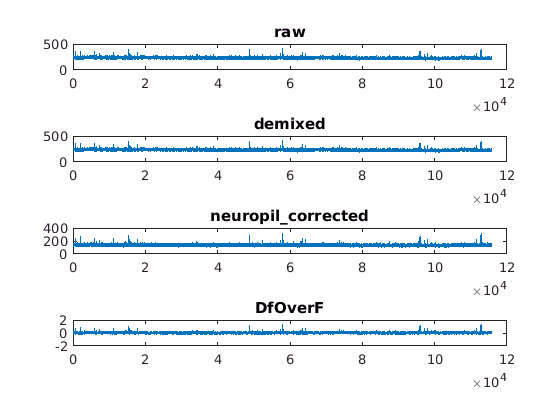

cell_specimen_id = 529022196;
%plot_fluorecence_traces(...)
plot_fluorecence_traces_of_selected_cell_in_selected_session(boc.session_id,cell_specimen_id);

## 3c) transform data of the selected fluorescence trace of the selected subexperiment into raster format

raster_dir_name = [bot_dir_name, 'raster/'];

stimuli = 'drifting_gratings';
fluorescence_trace = DfOverF;

current_raster_dir_name = transform_fluorescenece_trace_into_raster_format(fluorescence_trace,...
    boc.session_id, stimuli,raster_dir_name);

/om/user/xf15/Brain-Observatory-Toolbox/raster/drifting_gratings_527745328/ already exists

## 4) Get Masks...